# RSN LAB 4 - Sensor Fusion (Driving)

load("calibration_parameters.mat");
load("data_drive_imu.mat");
load("data_drive_gps.mat");

mag_x_drive = data_drive_imu.MagField_magnetic_field_x;
mag_y_drive = data_drive_imu.MagField_magnetic_field_y;

R1 = calibration_params(:,(1:2));
R2 = calibration_params(:,(3:4));
bias = calibration_params(:,5);

mag_calibrated_data = R2 * R1^-1 * [mag_x_drive' - bias(1) ; mag_y_drive'- bias(2)];
mag_uncalibrated_data = ([mag_x_drive' ; mag_y_drive']);

yaw_mag_uncalibrated_wrapped = atan2(-mag_uncalibrated_data(2,:), mag_uncalibrated_data(1,:));
yaw_mag_calibrated_wrapped = atan2(-mag_calibrated_data(2,:), mag_calibrated_data(1,:));

## Time

time = data_drive_imu.Time - min(data_drive_imu.Time);

## Conversion and Unwrapping of Yaw

%converting yaw from radians to degree and unwrapping

% 90 is subtracted from the calibrated yaw to match it with the starting
% position of the gyroscope

yaw_mag_calibrated = rad2deg(unwrap(yaw_mag_calibrated_wrapped)) - 90; 

yaw_mag_uncalibrated = rad2deg(unwrap(yaw_mag_uncalibrated_wrapped));

% Calculating yae from magnetometer
qw = data_drive_imu.IMU_orientation_w;
qx = data_drive_imu.IMU_orientation_x;
qy = data_drive_imu.IMU_orientation_y;
qz = data_drive_imu.IMU_orientation_z;

% euler angle stores yaw, pitch and roll
euler_angles = quat2eul([qw qx qy qz]);
yaw_from_imu_unwrapped = euler_angles(:,1);

%Converting yaw from radians to degree and unwrapping
yaw_from_imu = rad2deg(unwrap(yaw_from_imu_unwrapped));

## Plotting Calibrated vs Uncalibrated Yaw from Magnetometer

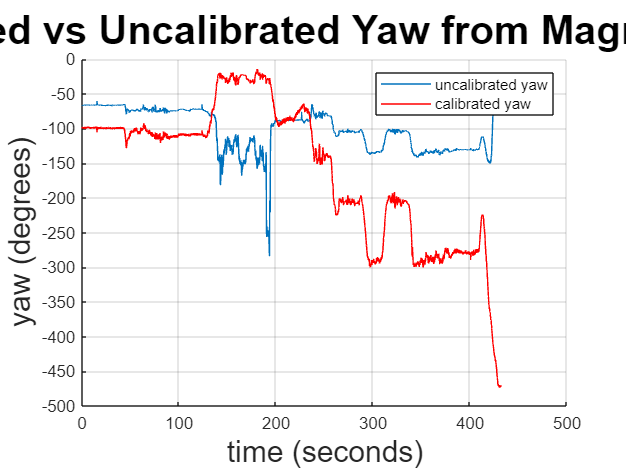

figure;
hold on;
grid on;
plot(time, (yaw_mag_uncalibrated), DisplayName='uncalibrated yaw');
plot(time, (yaw_mag_calibrated), DisplayName='calibrated yaw', Color='r');
xlabel('time (seconds)', FontSize=18);
ylabel('yaw (degrees)', FontSize=18);
title('Calibrated vs Uncalibrated Yaw from Magnetometer', FontSize=24);
legend;
hold off;

## Plotting magnetometer time series data

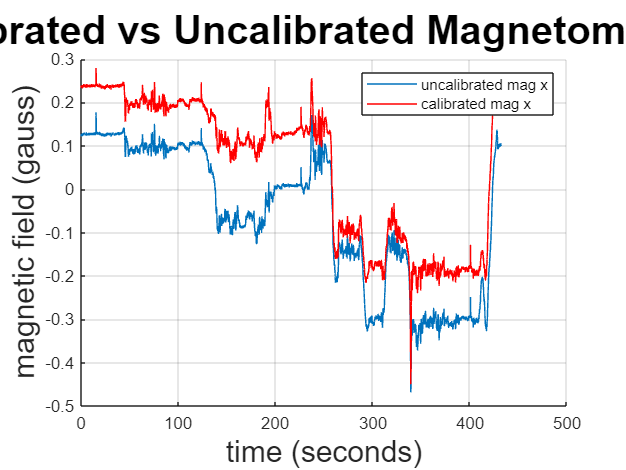

figure;
hold on;
grid on;
plot(time, (mag_uncalibrated_data(1,:)), DisplayName='uncalibrated mag x');
plot(time, (mag_calibrated_data(1,:)), DisplayName='calibrated mag x', Color='red');
xlabel('time (seconds)', FontSize=18);
ylabel('magnetic field (gauss)', FontSize=18);
title('Calibrated vs Uncalibrated Magnetometer X', FontSize=24);
legend;
hold off;

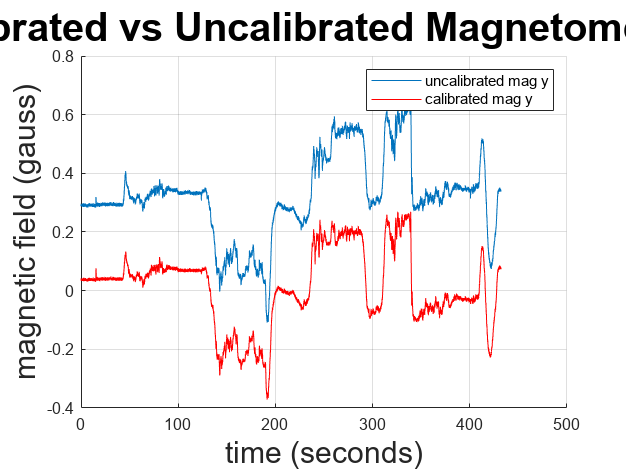


figure;
hold on;
grid on;
plot(time, (mag_uncalibrated_data(2,:)), DisplayName='uncalibrated mag y');
plot(time, (mag_calibrated_data(2,:)), DisplayName='calibrated mag y', Color='red');
xlabel('time (seconds)', FontSize=18);
ylabel('magnetic field (gauss)', FontSize=18);
title('Calibrated vs Uncalibrated Magnetometer Y', FontSize=24);
legend;
hold off;

## Integrating gyro Z for yaw

gyro_z = data_drive_imu.IMU_angular_velocity_z;
figure;

%Sampling time
ts = 1/40;

%Converting from rad to deg and unwrapping
yaw_from_gyro = rad2deg(cumsum(gyro_z) * ts) + yaw_from_imu(1);

## Plotting Yaw from Magnetometer, Gyroscope

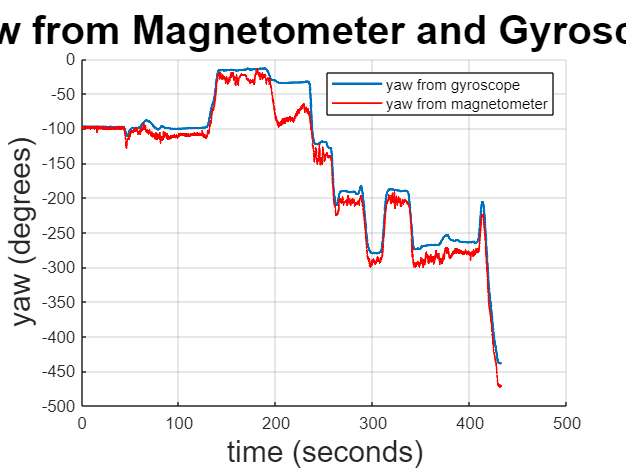

figure;
hold on;
grid on;
plot(time, yaw_from_gyro, DisplayName='yaw from gyroscope', LineWidth=1.5);
plot(time, yaw_mag_calibrated, DisplayName='yaw from magnetometer', Color='r', LineWidth=1);
xlabel('time (seconds)', FontSize=18);
ylabel('yaw (degrees)', FontSize=18);
title('Yaw from Magnetometer and Gyroscope', FontSize=24);
legend;
hold off;

## Complementary filter design

%Subtracting the first value of the arrays from itself to shift the data to 0. This is required to
%eliminate spikes in the filter data. Again unshifting after filtering (for mag data)

[b, a] = butter(2, 0.005, 'low');
mag_low_pass = filter(b, a, (yaw_mag_calibrated - yaw_mag_calibrated(1))) + yaw_mag_calibrated(1);

[b, a] = butter(5, 0.005, 'high');
gyro_high_pass = filter(b, a, (yaw_from_gyro' - yaw_from_gyro(1)));

% Complementary Filter
yaw_from_filter = mag_low_pass + gyro_high_pass;

## Plotting the complementary filter output

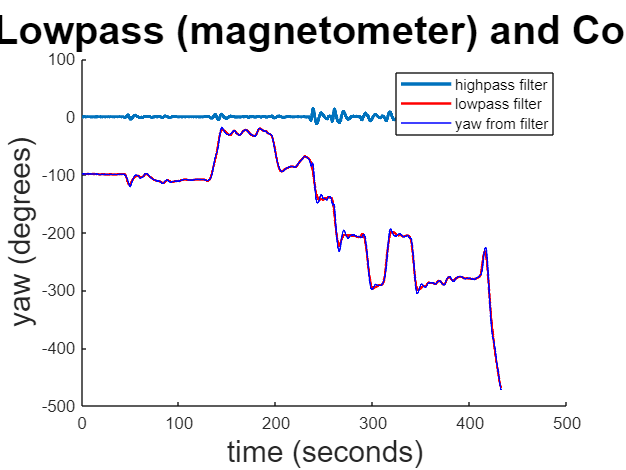

figure;
hold on;
plot(time, (gyro_high_pass), DisplayName='highpass filter', LineWidth=2);
plot(time, (mag_low_pass), DisplayName='lowpass filter', LineWidth=1.5,  Color='r');
plot(time, (yaw_from_filter), DisplayName='yaw from filter', LineWidth=1, Color='b');
xlabel('time (seconds)', FontSize=18);
ylabel('yaw (degrees)', FontSize=18);
title('Highpass (gyro), Lowpass (magnetometer) and Complementary Filter', FontSize=24);
legend;
hold off;

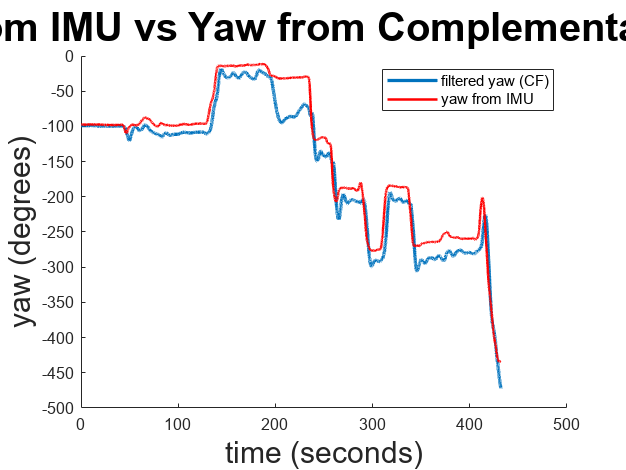


figure;
hold on;
plot(time, (yaw_from_filter), DisplayName='filtered yaw (CF)', LineWidth=2);
plot(time, (yaw_from_imu), DisplayName='yaw from IMU', LineWidth=1.5, Color='r');
xlabel('time (seconds)', FontSize=18);
ylabel('yaw (degrees)', FontSize=18);
title('Yaw from IMU vs Yaw from Complementary Filter', FontSize=24);
legend;
hold off;

## Calculating velocity from GPS

%Subtracting the first value of utm_e and utm_n from the data
utm_e = data_drive_gps.UTM_easting - data_drive_gps.UTM_easting(1);
utm_n = data_drive_gps.UTM_northing - data_drive_gps.UTM_northing(1);
time_gps = data_drive_gps.Time - min(data_drive_gps.Time);

vel_e = zeros(size(utm_e));
vel_n = zeros(size(utm_n));
prev_val_e = 0;
prev_val_n = 0;

for i=1:size(utm_e)
    vel_e(i) = utm_e(i) - prev_val_e;
    vel_n(i) = utm_n(i) - prev_val_n;
    prev_val_e = utm_e(i);
    prev_val_n = utm_n(i);
end

vel_gps = vecnorm([vel_e' ; vel_n']);
vel_gps_interp = interp1(time_gps, vel_gps, time);

utm_e_interp = interp1(time_gps, utm_e, time);
utm_n_interp = interp1(time_gps, utm_n, time);

## Velocity Estimation

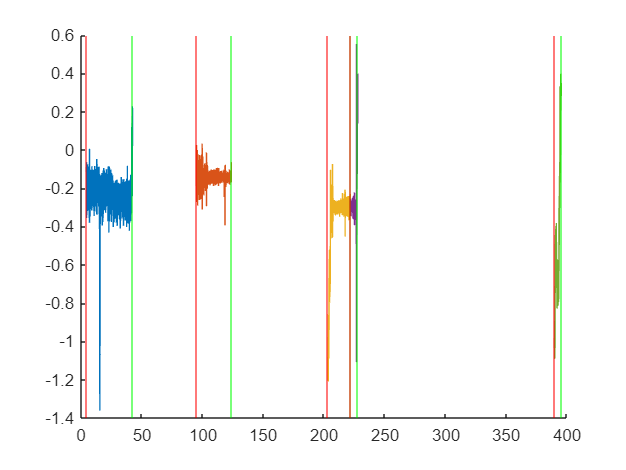

acc_x = data_drive_imu.IMU_linear_acceleration_x;
acc_y = data_drive_imu.IMU_linear_acceleration_y;
acc_z = data_drive_imu.IMU_linear_acceleration_z;
acc_norm = movmean(vecnorm([acc_x' ; acc_y' ; acc_z']), 5);

counter = 0;
bias = 0;

acc_x_unbiased = acc_x;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%THIS IS THE FINAL CODE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
hold on;
for i = 1:numel(acc_x)
    if(acc_norm(i) <= 9.85 && acc_norm(i) >= 9.65)
        if(counter == 0)
            start_time = i;
        end
        counter = counter + 1;
    else
        if counter >= 120
            end_time = i;
            bias = mean(rmoutliers(acc_x(start_time:end_time), "mean"));
            %bias = mean(acc_x(start_time:end_time));

            acc_x_unbiased(start_time:end_time) = 0;
            %acc_x_unbiased(start_time:end_time) = acc_x(start_time : end_time) - bias;
            %acc_x_unbiased(start_time:end) = acc_x(start_time : end) - bias;

            plot(time(start_time:end_time),acc_x(start_time:end_time));
            xline(time(start_time), 'r');
            xline(time(i), 'g');
            %disp(bias);
            counter = 0;
            continue
        end
        counter = 0;
    end
    acc_x_unbiased(i) = acc_x(i) - bias;
end

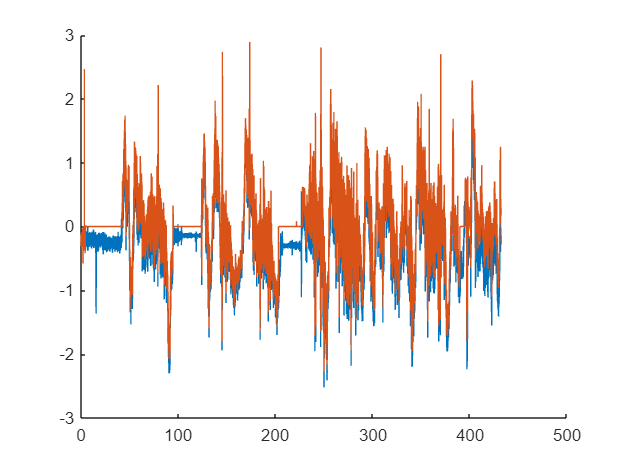

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure;
hold on;
plot(time, acc_x);
plot(time, acc_x_unbiased);
hold off;


%Integrating unbiased acceleration
prev_sum = 0;
vel_x_unbiased = zeros(size(acc_x_unbiased));
for i = 1:numel(acc_x_unbiased)
    vel_x_unbiased(i) = (acc_x_unbiased(i))*ts + prev_sum;
    
    if(vel_x_unbiased(i) < 0)
        vel_x_unbiased(i) = 0;
    end
    prev_sum = vel_x_unbiased(i);
end

## Plotting the biased and unbiased velocities

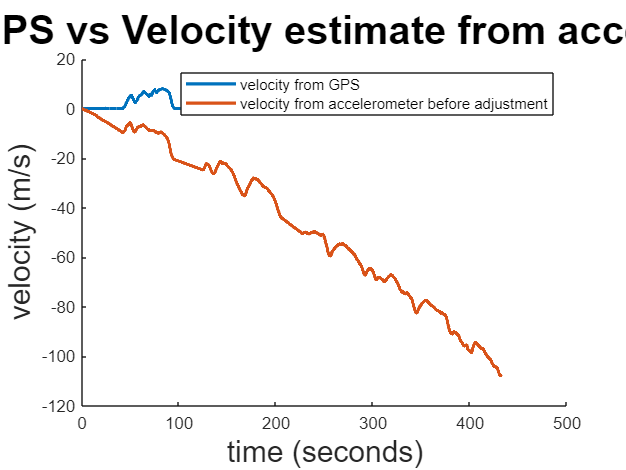

figure;
hold on;
plot(time, vel_gps_interp, DisplayName='velocity from GPS', LineWidth=2);
plot(time, cumsum(acc_x)*ts, DisplayName='velocity from accelerometer before adjustment', LineWidth=2);
xlabel('time (seconds)', FontSize=18);
ylabel('velocity (m/s)', FontSize=18);
title('Velocity estimate from the GPS vs Velocity estimate from accelerometer before adjustment', FontSize=24);
legend;
hold off;

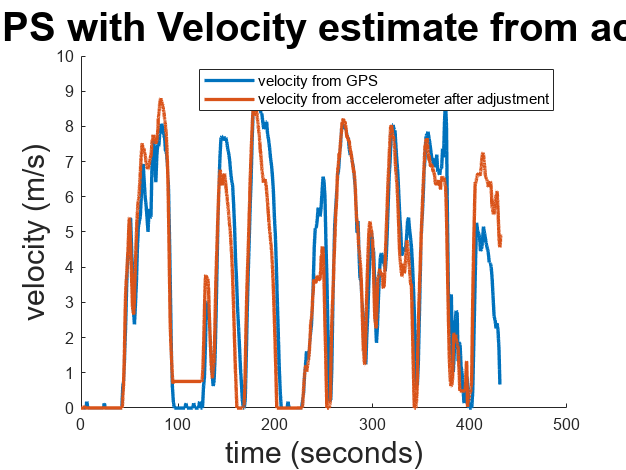


figure;
hold on;
plot(time, vel_gps_interp, DisplayName='velocity from GPS', LineWidth=2);
plot(time, vel_x_unbiased, DisplayName='velocity from accelerometer after adjustment', LineWidth=2);
xlabel('time (seconds)', FontSize=18);
ylabel('velocity (m/s)', FontSize=18);
title('Velocity estimate from the GPS with Velocity estimate from accelerometer after adjustment', FontSize=24)
legend;
hold off;

## Comparison of acceleration in Y and coriolis acceleration

acc_y_smooth = movmean(acc_y-mean(acc_y), 15);
w_x_dot = vel_x_unbiased.*gyro_z;

## Plotting the coriolis acceleration and acceleration in Y axis

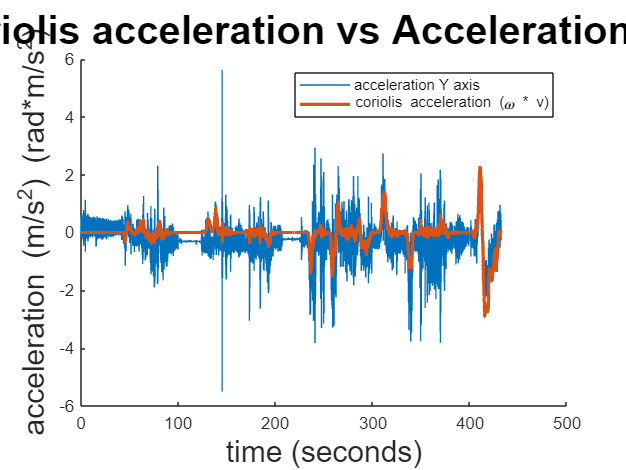

figure;
hold on;
plot(time, acc_y, DisplayName='acceleration Y axis', LineWidth=0.25);
plot(time, w_x_dot, DisplayName='coriolis acceleration (\omega * v)', LineWidth=2);
xlabel('time (seconds)', FontSize=18);
ylabel('acceleration (m/s^2) (rad*m/s^2)', FontSize=18);
title('Coriolis acceleration vs Acceleration in Y', FontSize=24);
hold off;
legend;

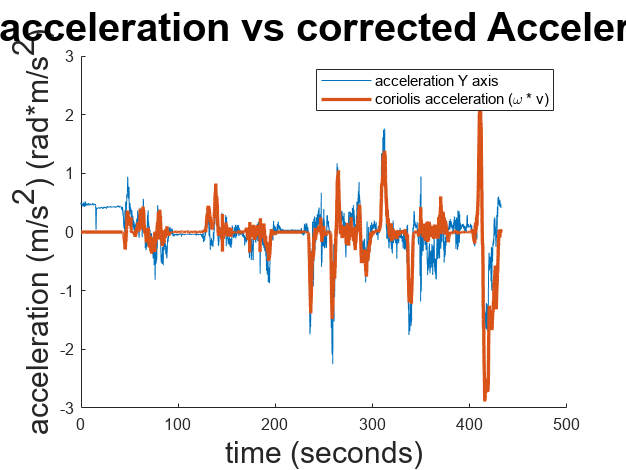


figure;
hold on;
plot(time, acc_y_smooth, DisplayName='acceleration Y axis', LineWidth=0.5);
plot(time, w_x_dot, DisplayName='coriolis acceleration (\omega * v)', LineWidth=2);
xlabel('time (seconds)', FontSize=18);
ylabel('acceleration (m/s^2) (rad*m/s^2)', FontSize=18);
title('Coriolis acceleration vs corrected Acceleration in Y', FontSize=24);
hold off;
legend;

## Estimation of Ve and Vn from magnetometer yaw

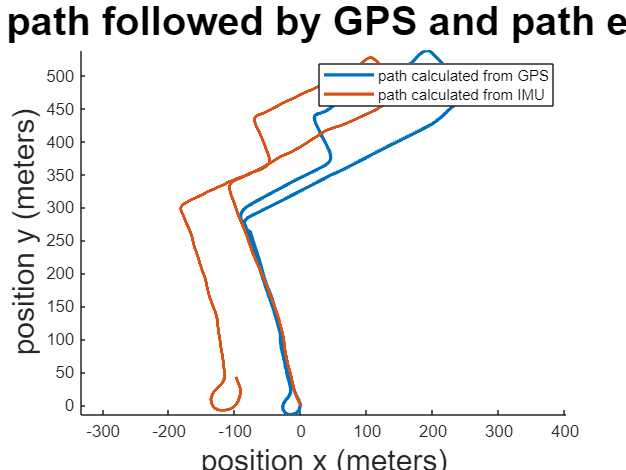

vel_e_calc = vel_x_unbiased' .* sin(yaw_mag_calibrated_wrapped);
vel_n_calc = vel_x_unbiased' .* cos(yaw_mag_calibrated_wrapped);

pos_e_calc = cumtrapz(vel_e_calc)*ts;
pos_n_calc = cumtrapz(vel_n_calc)*ts;

figure;
hold on;
plot(utm_e, utm_n, DisplayName='path calculated from GPS', LineWidth=2);
plot(pos_e_calc, pos_n_calc, DisplayName='path calculated from IMU', LineWidth=2);
xlabel('position x (meters)', FontSize=18);
ylabel('position y (meters)', FontSize=18)
title('Comparison of path followed by GPS and path estimated by IMU', FontSize=24);
axis equal;
legend;

## Distance between GPS position and IMU position (Dead Reckoning)

dist = sqrt((pos_e_calc' - utm_e_interp).^2 + (pos_n_calc' - utm_n_interp).^2);

dist_accumulated = cumsum(dist);
disp(dist_accumulated(400));

   31.0719



%Getting the time where dist between GPS path and IMU path is >2m 
for i=1:numel(dist)
    if(dist(i)>2)
        disp(i/40);
        break
    end
end

   52.2750

